clc;clear;

load('C:\Users\Arshia\Desktop\StableLearningInBiologicalSNN\Analysis\Part3(ClassificationSequential)\Data\N400\nMems25\May_22_2025_03_41_32\Recalls\alpha50\recalls25.mat')
whos

  Name                    Size                 Bytes  Class     Attributes

  delays               5000x400             16000000  double              
  groups                  1x5000              270112  string              
  orders_separate      5000x400             16000000  double              
  orders_together      5000x400             16000000  double              
  spikeCounts          5000x400             16000000  double              



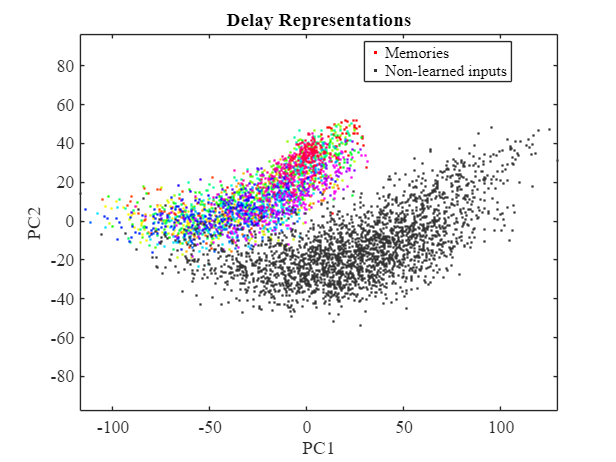

[coeff, score, latent, tsquared, explained] = pca(delays);

figure; hold on;
cmap = hsv(25); % 25 distinct colors

% Plot one dummy point for legend (memories)
h1 = scatter(nan, nan, 20, cmap(1,:), '.', 'DisplayName', 'Memories');

% Plot all memory points without legend entries
for m = 1:25
    idx = 1 + (m-1)*100 : m*100;
    scatter(score(idx, 1), score(idx, 2), 20, cmap(m, :), '.', ...
        'HandleVisibility', 'off');
end

% Plot one dummy point for non-learned inputs
h2 = scatter(nan, nan, 15, [0.2 0.2 0.2], '.', 'DisplayName', 'Non-learned inputs');

% Plot all non-learned inputs without legend entries
scatter(score(2501:end, 1), score(2501:end, 2), 20, [0.2 0.2 0.2], '.', ...
    'HandleVisibility', 'off');

title("Delay Representations");
xlabel("PC1");
ylabel("PC2");
legend([h1, h2], 'Location', 'best');
axis equal;
box on;

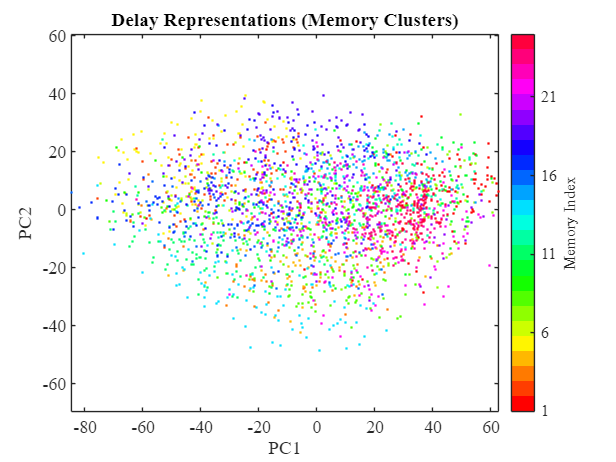


[coeff, score, latent, tsquared, explained] = pca(delays(1:2500, :));

figure; hold on;

% Prepare memory labels
memory_ids = repelem(1:25, 100)'; % 100 samples per memory class
cmap = hsv(25);                   % Define colormap

% Create scatter plot with memory-based coloring
scatter_handle = scatter(score(:,1), score(:,2), 20, memory_ids, '.', ...
    'DisplayName', 'Memories');

% Apply colormap and colorbar
colormap(cmap);
c = colorbar;
c.Label.String = 'Memory Index';
c.Ticks = 1:5:25; % Optional: fewer ticks for readability

% Labeling and formatting
title("Delay Representations (Memory Clusters)");
xlabel("PC1");
ylabel("PC2");
axis equal;
box on;